% %function hw1_template()

# Homework 1: HIV Drug Response

In this homework, you will analyze data from HIV patients. Patients receiving different therapy regimens were monitored for their blood viral load. You are asked to determine which therapy regimen provides the best treatment.

Update this template file with your codes and comments.

## Description of Data

The file patientdata.xlsx contains patient data collected from 5000 HIV patients.

- Column-1 represents the patient's Age at intake

- Column-2 represents the drug regimen

- Column-3 represents the Viral Load (copies/mL) at intake

- Column-4 to Column-8 is the Viral Load measured at 6 month intervals.

- Drug-regimen #1 is a placebo control.

## Variable names and acronyms used in this file

- **m**: The patient data matrix, each row is a patient and columns are as described above.

- **vl**: Viral load.

- **dvl**: Change in viral load.

- The terms group/drug/treatment are used interchangeably.

## Objectives:

- Understand the data

- Read an excel file into a cell array with xlsread()

- Use logical index array to select certain data. I = m(:, groupcol) == 1; ageofgroup1=m(I,agecol). 

- Plot, captions and conclusions

## **  Best practice:**

- comment out all the example codes 

## Read the patient data file

% % %xlsread is slow. Can you find a way to make this step run faster?
% % %https://www.mathworks.com/help/matlab/ref/xlsread.html
% % %[num,txt,raw,custom] = xlsread(filename,sheet,xlRange,'',processFcn)
% % %returns numeric value to num, the text fields in cell array txt,
% % %and both numeric and text data in cell array raw
% % %trying to refresh your understanding of data type matrix and cell array.
% % %practice xlsread by reading cell range B2:C3; column C;
% 
% % read in the data using xlsread()
[m,txt,raw] = xlsread('patientdata.xlsx'); 
fields = raw(1,:);
fields

fields = 1×8 cell array
    {'age'}    {'drugregimen'}    {'viralload0'}    {'viralload1'}    {'viralload2'}    {'viralload3'}    {'viralload4'}    {'viralload5'}


1 0 0 0 0 0 0 0
% 
  1 2 3 4

Invalid expression. Check for missing multiplication operator, missing or unbalanced delimiters, or other syntax error. To construct matrices, use brackets instead of parentheses.

# Check to make sure the groupings/drug regiment are random in age

The goal of this section is to  find the average age of individuals on different drug regiments (age column and drugregimen column). The template codes are listed below. The key is to  generate the 500x1 logical index based on drugregimens (who are taking drug 1,....), then use the logical index I to select the individuals and calculate average age in the age column. 

% % %It's important that the initial groupings of patients into drug regimens
% % %are not skewed. First, we'll check the *age*.
% % 
% % % Calculate the average age of all patients.
% % % Hint: mean()
avg_age = [];
% % 
% % 
% % 
% % % %Find Text in Cell Array, return what?
% % % % X=strcmp(fields, 'age');
% % % % k = find(X) returns a vector containing the linear indices of each nonzero element in array X.
% % % % agecol, groupcol and numgroups (number of groups)
% % 
agecol = find( strcmp(fields, 'age') ); % agecol=1
% % % 
% % % % strcmp(fields, 'drugregimen');
% % 
groupcol = find( ? );   % groupcol=2
% groups = unique(m(:,strcmp(fields, "drugregimen")))
% splitapply(@mean, m(:,1), m(:, 2))
% numgroups = max( m (:,groupcol)); %find the number of groups =4
% 
% % Find the average age of patients broken down by drug-regimen.
% % mean(m(m(:, strcmp(fields, "drugregimen")) == 1, 1))
% % Hint: for loop for each drug regimen, logical indexing, mean().
% %I = m(:,groupcol) == gi; return a 500x1 logical vector I for each treatment
% %agesofthisgroup = m(I, agecol);
avg_groupage = zeros(1,numgroups);

std_groupage = zeros(1,numgroups);
% 
for gi = 1:numgroups 
   	I = m(:,groupcol) == gi
      agesofthisgroup = m(I, agecol)
      avg_groupage=mean(agesofthisgroup)
       std_groupage=.....
end
% I
% % you will have avg_groupage( 1 ); avg_groupage( 2 ); avg_groupage( 3 );avg_groupage( 4 )

## Plot Age Data

Put this data into a bar-plot. Do you notice anything? How would you be able to tell if the data was askew? 

% bar( ? );
% hold on;
% errorbar( ? );
% hold off;
% xlabel('?')
% ylabel('?')

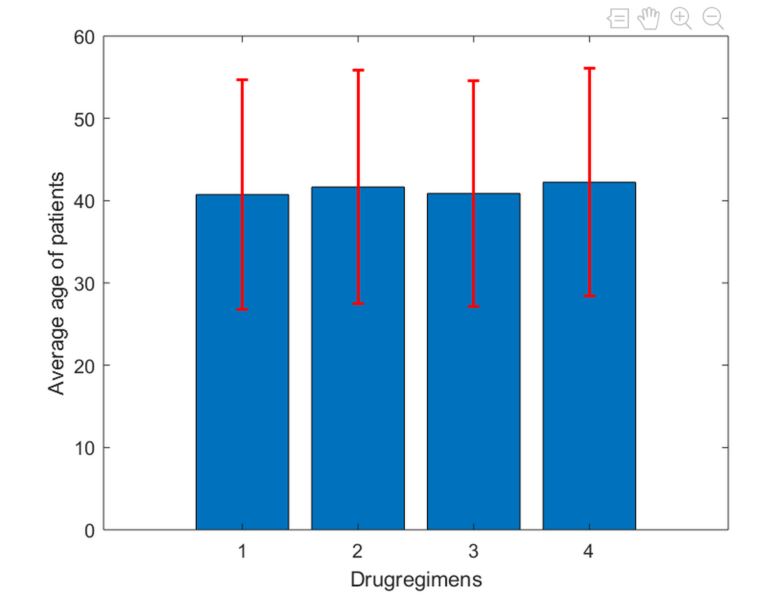

## Captions

All captions should have the following: - Title Sentence: This should deliver the main point of the figure - Explanation of the source of the data behind each plot. - Explanation of all axes.

**Figure captions.** The average age of individuals on different drug regiments. 

## Conclusions 

conclusions

draw reasonable conclusions baseed on figures

# Let's look at and plot  the data in a different way to address the same question. 

 What else could you include to help visualize any potential differences? what about a histogram? 

% 
% subplots_vec = [221 222 223 224];
% for gi = 1:numgroups
%    	????
%     histogram(?, 40);
%     title(sprintf('Drugregimen %g', gi));
%     xlabel('Age');
%     ylabel('Frequency');
%     axis([15 70 0 10]);
% end

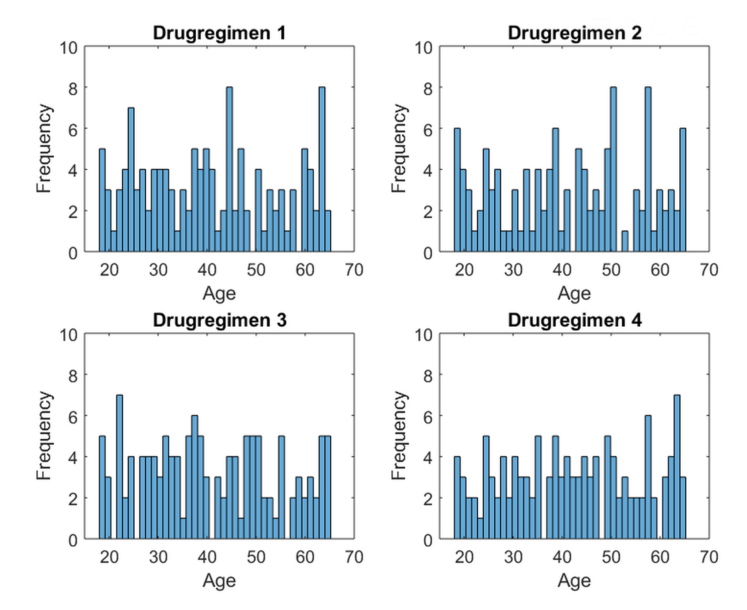

## Captions

## Conclusions 

# Check to make sure the groupings are random in initial health (viralload0).

It is important to note that you should use **log-scale** values when looking at viral loads

% % Find the average intake VL of all patients
% avg_vl = [];
% 
% viralload0_col = find( ? );
% 
% avg_group_viralload0 = zeros(1,numgroups);
% std_group_viralload0 = zeros(1,numgroups);
% 
% figure;
% for gi = 1:numgroups
%    	?????
%     log_viralload0_group = log10(viralload0_group);
% end

## Plot Viral Load Data

Put this data into a bar-plot, do you notice anything? How would you be able to tell if the data was askew. What else could you include to help visualize any potential differences?

% bar( avg_group_viralload0 );
% hold on;
% errorbar( avg_group_viralload0, std_group_viralload0, 'r', 'LineWidth',1.5, 'LineStyle','none' );
% hold off;
% xlabel('Drugregimens')
% ylabel('Average log10(Viral Load 0)')

## Captions

## Conclusions 

## Plot Viral Load Data

How would you be able to tell if the data was askew. What else could you include to help visualize any potential differences? try to plot in a histogram

% figure
% % Find the average intake VL of patients broken down by drug-regimen
% subplots_vec = [221 222 223 224];
% for gi = 1:numgroups
%    	?????
%     histogram(log10(viralload0_ofthisgroup),20)
%     title(sprintf('Drugregimen %g', gi));
%     xlabel('log10(Viral Load 0)');
%     ylabel('Frequency');
%     axis([2.8 5.2 0 15]);
% end

## Captions

## Conclusions 

# Which therapy worked best?

While this may seem like a simple question, there are many ways to evaluate the answer. We'll look at a two.

# Evaluate therapies by fraction of minimum detectable level patients

We'll look at how many patients decreased to the minumum detectable level of viral load. In this dataset that's 48 copies/mL.

any entries where viralload == 48 -> BDL -> therapy effective

% % What fraction of patients were at the minimum detection threshold at the
% % final timepoint?
% curedratio = [];
% 
% % When broken down by treatment?
% groupcuredratio = zeros(1,4);

## Plot Ratios of Patients at Minimum Detection

When you plot these, what do you see? Which treatment is the most effective by this measure? The ratio should be the total number of individuals with less than 48 viralloads over the total number of patients in this group. 

% % number of patiens below or equal to 48 over total patients in this group
% 
viralloads = m(:, 3 : end);
% % Test the rows of viralloads for  elements<48  by specifying dim = 2
cured = any( viralloads <= 48, 2 ); % if any element<=48 across the row. 
% I is the logic vector for patients belong to which group(drugregiment)
for gi = 1:numgroups
    I=
    Cureofthisgroup=cured(I);
    groupcuredratio =sum(cured(I))/numel (cured(I)); 
end
% bar(groupcuredratio);
% ylabel('Fraction Below 48 copies/mL');
% xlabel('Drugregimen #');

## Captions

## Conclusions 

# Evaluate therapies by rate of change.

Another way to measure the effectiveness of the therapies is to look at the rate of change induced as a function of therapy. For this, we will use the diff**()** function in Matlab. Calculate the difference between each month (each visit) and compare the average across the different drug groups.

The 500x6 will change to 500X5.   

% % for each patient over all time periods.  PAY ATTENTION TO UNITS. You want them in
% % log10(copies/mL)/month. -> use log to compress data range
% 
% % For each patient
num_viralloads = 6;
[numpatients, ~] = size(m);
patientdvl = zeros(size(m, 1), num_viralloads - 1);
for i = 1 : numpatients
    patientdvl(i, :) = diff(log10(m(i, 3 : end)));
end

## Plot Rate of Change in Viral Load

When you plot these, what do you see? Which treatment is the most effective by this measure?

% figure;
% hold on;
% 
% % Now average those into a per-drug vector.
% groupdvl = zeros(4,5);
% group_std_dvl = zeros(4,5);
% for gi = 1:numgroups
%    	I = m(:,groupcol) == gi;
%    	????
%     errorbar(1 : 5, -groupdvl(gi, :),group_std_dvl(gi, :), '-x');
%     xlabel('Month');
%     ylabel('Average Change in Viral Load ( log10(copies/mL)/month )');
% end
% 
% legend('Drugregimen 1', 'Drugregimen 2', 'Drugregimen 3', 'Drugregimen 4');

## Captions

## Conclusions

## Bonus to A+: (5 points)

What about using polyfit() to caculate the rate of change between months,  and plot the average slope of each drugregimen. 